% Task 1

v = [1; 2; 3]

v =      1
     2
     3


w = [4; 5; 6]

w =      4
     5
     6



A = [0 2 -8;
    3 5 4;
    -1.5 -1 1]

A =          0    2.0000   -8.0000
    3.0000    5.0000    4.0000
   -1.5000   -1.0000    1.0000


B = [4 4 0;
    1 4 0;
    -1 -2 2]

B =      4     4     0
     1     4     0
    -1    -2     2



a = 10

a = 10

b = 20

b = 20


dot_prod = dot(v, w)

dot_prod = 32

norm_v = norm(v)

norm_v = 3.7417

norm_w = norm(w)

norm_w = 8.7750


A_inv_times_B = A \ B

A_inv_times_B =     0.1111    0.6667   -1.7778
    0.4444    0.6667    0.8889
   -0.3889   -0.3333    0.2222


A_times_B_inv = A / B

A_times_B_inv =    -0.8333   -0.6667   -4.0000
    0.9167    1.3333    2.0000
   -0.3333    0.3333    0.5000



AB_inv = inv(A * B)

AB_inv =    -0.1111   -0.1111   -0.4444
    0.0694    0.0833    0.2222
   -0.0278    0.0556    0.0556



B_det = det(B)

B_det = 24

B_rank = rank(B)

B_rank = 3

B_trace = trace(B)

B_trace = 10

[B_eigenvecs, B_eigenvals] = eig(B)

B_eigenvecs =          0    0.8165    0.8900
         0    0.4082   -0.4450
    1.0000   -0.4082   -0.0995


B_eigenvals =      2     0     0
     0     6     0
     0     0     2



eqn_roots =  roots([a b 0])

eqn_roots =      0
    -2


x1 = eqn_roots(1)

x1 = 0

x2 = eqn_roots(2)

x2 = -2

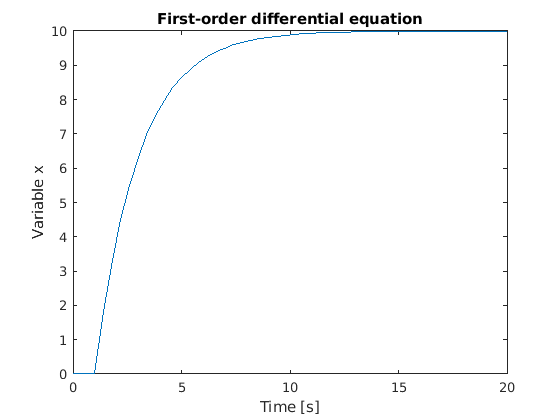

% Task 2 & 3: simulink example
tau = 0.5;
x0 = 0;
stept = 1;
stepi = 0;
stepf = 10;

sim('egb445/CompLab1_1.slx')

plot(mytime, x)
title('First-order differential equation')
xlabel('Time [s]')
ylabel('Variable x')

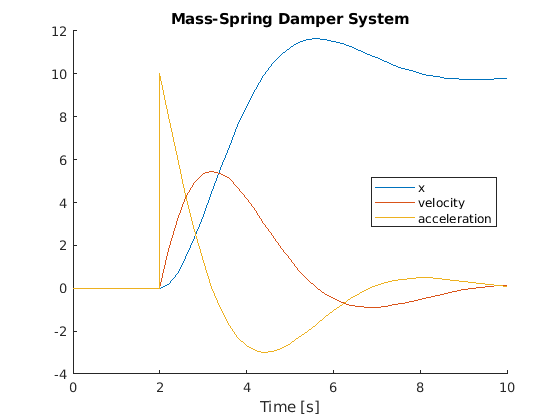

% Task 4: Mass-spring damper system
m = 1;
k = 1;
b = 1;
x0 = 0;
dx0 = 0;
ddx0 = 0;
extforce = 1;
stept = 2;

sim('egb445/CompLab1_2.slx')

figure; 
hold on;
title('Mass-Spring Damper System')
xlabel('Time [s]')
plot(mytime, pos)
plot(mytime, vel)
plot(mytime, acc)
legend('x', 'velocity', 'acceleration', 'location', 'east')

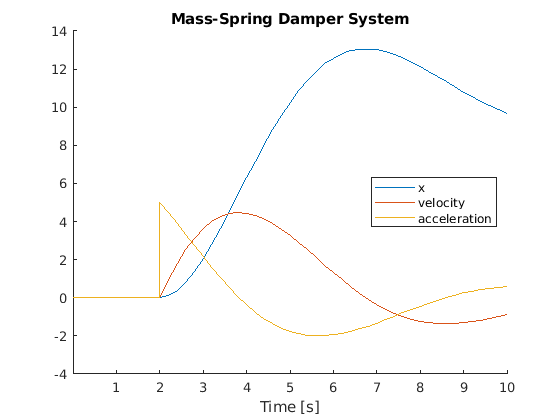

m = 2;
k = 1;
b = 1;
x0 = 0;
dx0 = 0;
ddx0 = 0;
extforce = 1;
stept = 2;

sim('egb445/CompLab1_2.slx')

figure; 
hold on;
title('Mass-Spring Damper System (Double Mass)')
xlabel('Time [s]')
plot(mytime, pos)
plot(mytime, vel)
plot(mytime, acc)
legend('x', 'velocity', 'acceleration', 'location', 'east')

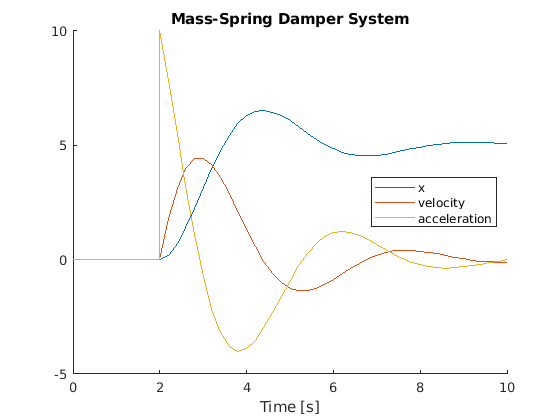

% Task 4: Mass-spring damper system double spring
m = 1;
k = 2;
b = 1;
x0 = 0;
dx0 = 0;
ddx0 = 0;
extforce = 1;
stept = 2;

sim('egb445/CompLab1_2.slx')

figure; 
hold on;
title('Mass-Spring Damper System (Double Spring)')
xlabel('Time [s]')
plot(mytime, pos)
plot(mytime, vel)
plot(mytime, acc)
legend('x', 'velocity', 'acceleration', 'location', 'east')

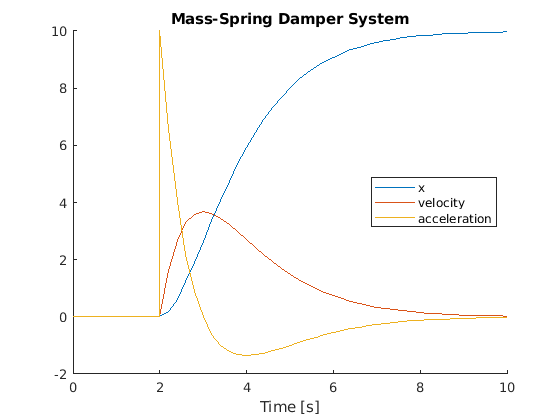

% Task 4: Mass-spring damper system
m = 1;
k = 1;
b = 2;
x0 = 0;
dx0 = 0;
ddx0 = 0;
extforce = 1;
stept = 2;

sim('egb445/CompLab1_2.slx')

figure; 
hold on;
title('Mass-Spring Damper System (Double Damp)')
xlabel('Time [s]')
plot(mytime, pos)
plot(mytime, vel)
plot(mytime, acc)
legend('x', 'velocity', 'acceleration', 'location', 'east')

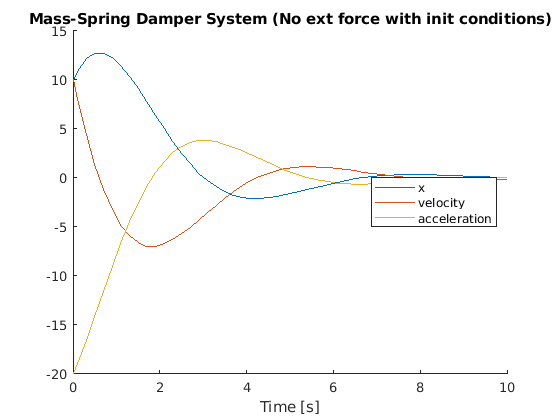

% Task 4: Mass-spring damper system
m = 1;
k = 1;
b = 1;
x0 = 10;
dx0 = 10;
extforce = 0;
stept = 0;

sim('egb445/CompLab1_2.slx')

figure; 
hold on;
title('Mass-Spring Damper System (No ext force with init conditions)')
xlabel('Time [s]')
plot(mytime, pos)
plot(mytime, vel)
plot(mytime, acc)
legend('x', 'velocity', 'acceleration', 'location', 'east')